# Thermoeconomic Analysis of a steam and electricity cogeneration plant

This Live Script performs a Thermoeconomic Analysis of a cogeneration plant based on a steam Rankine cycle using TaesLab functions.

The plant produces 10 MW of electricity and 10 kg/s of steam at reference conditions.

We analyze the efficiency of the plant and the costs of steam and electricity as a function of the cogeneration flow rate.

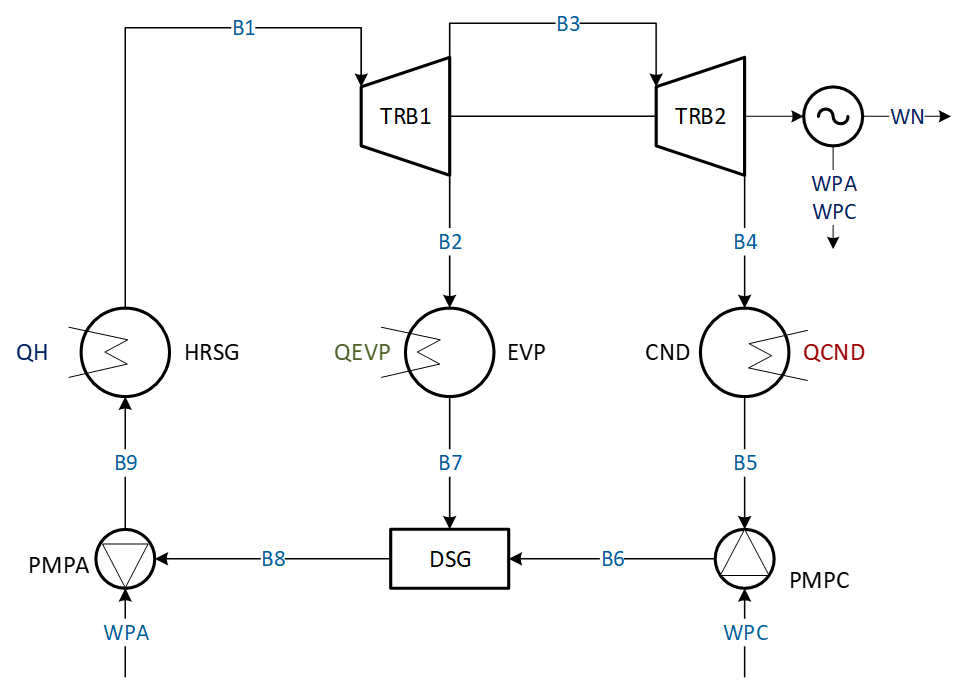

#### 1. Read the data model file

This function reads the data model file and loads it as a MATLAB object

model=ThermoeconomicModel('scgp_model.xlsx',...
    'Summary','STATES',...
    'DiagnosisMethod','WASTE_INTERNAL');

INFO: cReadModelXLS. Optional Sheet WasteAllocation is not available
INFO: cReadModelXLS. Optional Sheet ResourcesCost is not available
INFO: cDataModel. Productive Structure is valid
INFO: cDataModel. Format Definition is valid
INFO: cDataModel. Exergy values [M10] are valid
INFO: cDataModel. Exergy values [M09] are valid
INFO: cDataModel. Exergy values [M08] are valid
INFO: cDataModel. Exergy values [M07] are valid
INFO: cDataModel. Exergy values [M06] are valid
INFO: cDataModel. Exergy values [M05] are valid
INFO: cDataModel. Exergy values [M04] are valid
INFO: cDataModel. Exergy values [M03] are valid
INFO: cDataModel. Exergy values [M02] are valid
INFO: cDataModel. Waste Definition is valid
INFO: cDataModel. No Resources Cost Data available
INFO: cDataModel. Data model scgp_model is valid
INFO: cThermoeconomicModel. Set reference state M10
INFO: cThermoeconomicModel. Set active waste QCND
INFO: cThermoeconomicModel. Recycle is not active
INFO: cThermoeconomicModel. Summary mode is

#### 2.Show the results for the base case

setDebug(model,false);
ShowResults(model)


Flows Definition Table - M10

  Id Key   From     To       Type      
————————————————————————————————————————
   1 B1    HRSG_P1  TRB1_F1  INTERNAL  
   2 B2    TRB1_F1  EVP_F1   INTERNAL  
   3 B3    TRB1_F1  TRB2_F1  INTERNAL  
   4 B4    TRB2_F1  CND_F1   INTERNAL  
   5 B5    CND_F1   PMPC_P1  INTERNAL  
   6 B6    PMPC_P1  DSG_P1   INTERNAL  
   7 B7    EVP_F1   DSG_F1   INTERNAL  
   8 B8    DSG_P1   PMPA_P1  INTERNAL  
   9 B9    PMPA_P1  HRSG_P1  INTERNAL  
  10 QH    ENV_R1   HRSG_F1  RESOURCE  
  11 WT1   TRB1_P1  GEN_F1   INTERNAL  
  12 WT2   TRB2_P1  GEN_F1   INTERNAL  
  13 WPC   GEN_P1   PMPC_F1  INTERNAL  
  14 WPA   GEN_P1   PMPA_F1  INTERNAL  
  15 WN    GEN_P1   ENV_O1   OUTPUT    
  16 QEVP  EVP_P1   ENV_O2   OUTPUT    
  17 QCND  CND_P1   ENV_W1   WASTE     


Productive Groups Definition Table - M10

  Id Key      Definition  Type      
—————————————————————————————————————
   1 HRSG_F1  QH          FUEL      
   2 HRSG_P1  B1-B9       PRODUCT   
   3 TRB1_F1  B

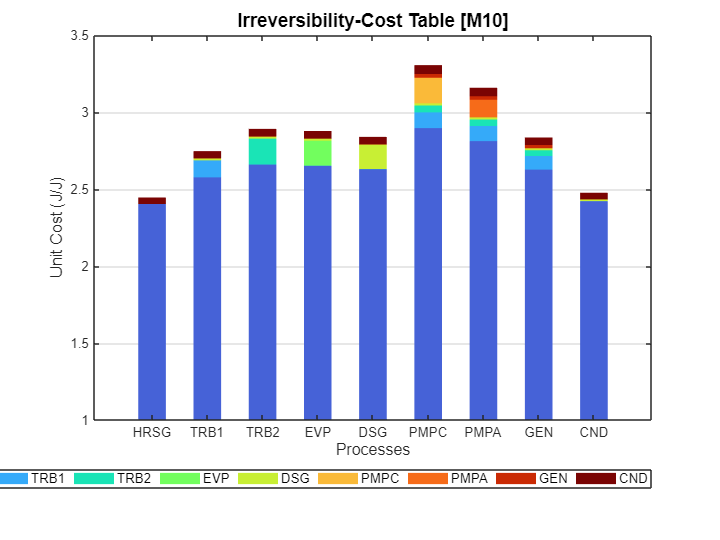

ShowGraph(model,'Graph','dict');

`The process with the lowest efficiency is the HRSG (41.63%); the rest of the components have an efficiency above 80%. The effect of condenser residues is not relevant in the reference case.`

#### 3. Summary Results

Get the summary results

sr=model.summaryResults;
ShowResults(sr);


Flows Exergy (kW) - SUMMARY

 key           M10       M09       M08       M07       M06       M05       M04       M03       M02
———————————————————————————————————————————————————————————————————————————————————————————————————
 B1        23306.0   22249.0   21192.0   20136.0   19079.0   18022.0   16966.0   15909.0   14853.0
 B2        11265.0   10139.0    9012.0    7886.0    6759.0    5633.0    4506.0    3380.0    2253.0
 B3         3036.0    3514.0    3992.0    4470.0    4948.0    5426.0    5904.0    6382.0    6861.0
 B4          373.9     432.8     491.7     550.5     609.4     668.3     727.2     786.1     845.0
 B5            5.8       6.8       7.7       8.6       9.5      10.4      11.3      12.3      13.2
 B6            9.3      10.8      12.2      13.7      15.2      16.6      18.1      19.5      21.0
 B7         1763.0    1587.0    1411.0    1234.0    1058.0     881.7     705.4     529.0     352.7
 B8         1547.0    1349.0    1156.0     968.7     788.9     618.3     459.1

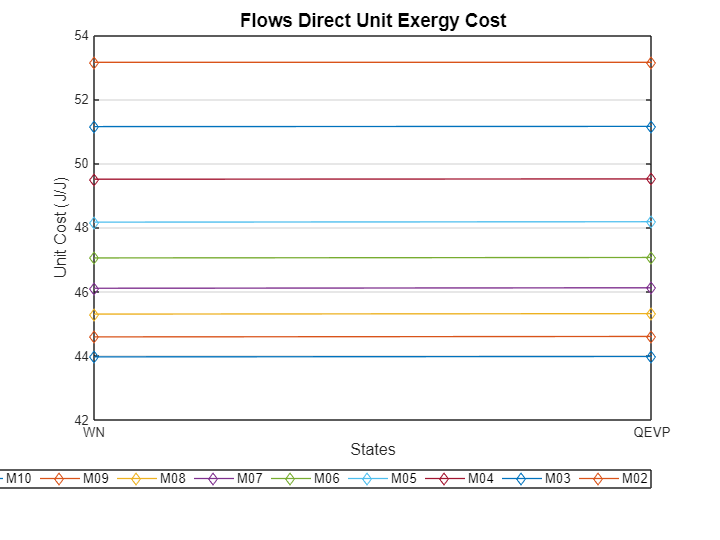

vars={'WN','QEVP'};
ShowGraph(sr,'Graph','dfuc','BarGraph',false,'Variables',vars);

`Electricity and and steam costs increase when steam production decreases from 10 kg/s to 2 kg/s. The heat dissipated in the condenser also increases. `

#### 4. Diagnosis Analysis

Analyze the plant when the steam mass flow decreases to 7 kg/s (30%)

setState(model,'M07');
model.summaryDiagnosis;


Fuel Impact:       -5557.00 (kW)
Technical Saving:   1711.81 (kW)



showResults(model,'dgn');


Diagnosis Summary - M07

Key        MF(kW)     ΔI(kW)     ΔR(kW)    ΔPt(kW)    MF*(kW)    MR*(kW)   ΔPt*(kW)
————————————————————————————————————————————————————————————————————————————————————
HRSG       686.52   -2992.00       0.00       0.00     686.52     629.55       0.00
TRB1         0.85    -120.00       0.00       0.00    -126.19      -3.77       0.00
TRB2        -0.86     179.40       0.00       0.00     -40.05      -1.19       0.00
EVP          0.69    -397.00       0.00   -2453.00    -133.67      -3.99   -7268.81
DSG        223.90      53.69       0.00       0.00     529.25      15.79       0.00
PMPC         0.00       0.27       0.00       0.00       0.01       0.00       0.00
PMPA         1.35      -1.90       0.00       0.00       3.86       0.12       0.00
GEN          0.24      -0.31       0.00       0.00     156.32       4.66       0.00
CND          0.00       0.00     173.85       0.00      -5.24      -0.16       0.00
ENV        912.70   -3277.85     173.85   -2453.0

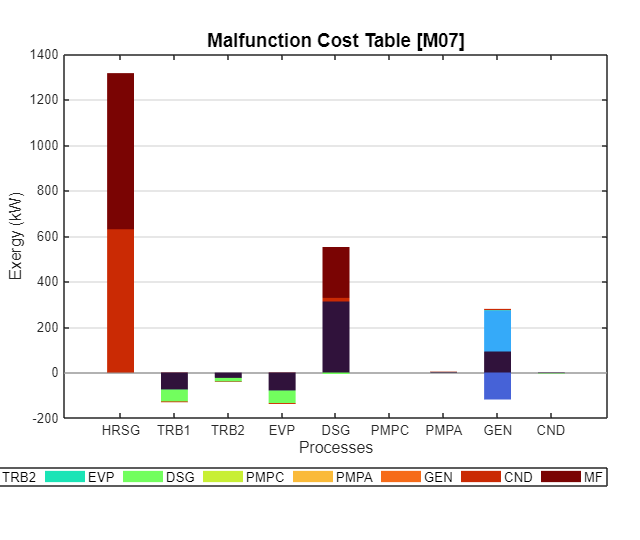

ShowGraph(model,'Graph','mfc','ShowOutput',false);

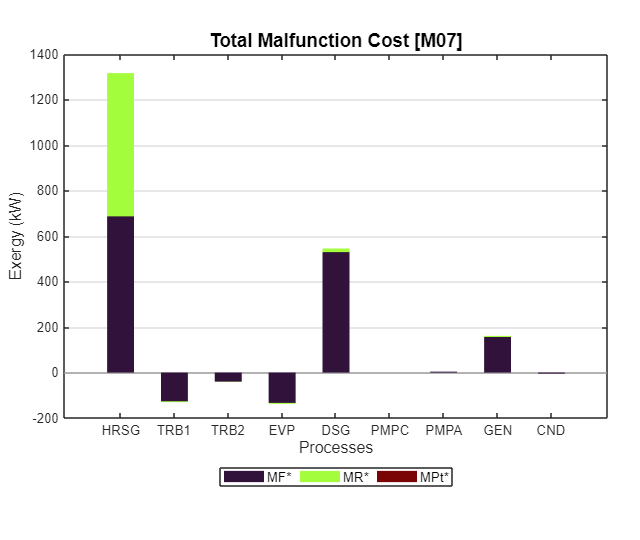

showGraph(model,'tmfc')

Although we consume less natural gas (5.5 MW), we also produce less steam (2.45 MW. In fact, with this reduction in steam production, the decrease in natural gas consumption should be 7.27 MW. 

This is because internal breakdown costs increase by 1.07 MW (dark bars), and condenser heat losses (green bar) increase by 0.64 MW.

As a consequence of the diagnostic analysis, we observe that when we reduce steam production, malfunctions in the boiler and the desuperheater increase, because the mass flow rate in the desuperheater also decreases, and therefore the boiler feedwater temperature decreases. 